%Q1

num = [0.5 1.25];       %Define Numerator
den = [1 2.5 -9.5 -21];     %Define Denominator
g_openloop = tf(num,den);        %Define tf
z = zero (g_openloop);       %Zeros of tf
p = pole (g_openloop);       %Poles of tf
S = isstable (g_openloop);       %We can see if its stable or not
minimal = minreal (g_openloop);      %We can see if tf is minimal or not

%Q2

[A,B,C,D] = tf2ss (num,den);        %Convert tf to ss
j = jordan (A);     %Lets see jordan form of matrix A, so we can make sure that it is minimal

%Q3

Co = ctrb (A,B);        %Compute the controllability matrix
rank (Co);      %Find the rank of controllability matrix (it is full rank)
Ob = obsv (A,C);     %Compute the observability matrix
rank (Ob);      %Find the rank of observability matrix (it is full rank)

%Q4
%It is minimal

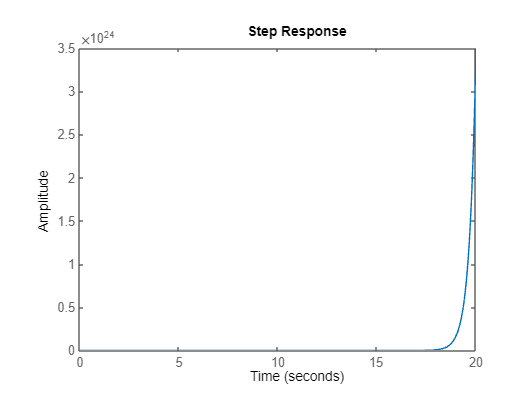

%Q5
%It is unstable
step (g_openloop); 

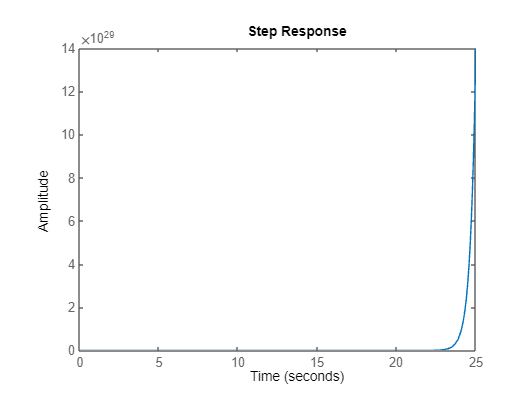

%Q6

g_closedloop = feedback (g_openloop,1);      %Compute closed loop tf
z1 = zero (g_closedloop);       %Zeros of closed loop tf
p1 = pole (g_closedloop);       %Poles of closed loop tf
step (g_closedloop);        %Step response of closed loop tf

%Q7

p = [-1 -2 -3];     %Define place of poles
K = acker (A,B,p);       %Compute K matrix
p2 = [-6 -7 -8];        %Define place of poles
K2 = acker (A,B,p2)      %Compute K matrix

K2 =    18.5000  155.5000  357.0000


%Q8

P = inv (C*inv(B*K - A)*B)      %Compute P matrix (P = G^(-1))

P = 4.8000

%Q9

V=[B,A;0,-C];        
rank(V);
p3 = [-1 -2 -3 -4];
A2 = [A,[0;0;0];-C,0];
B2 = [B;0];
K3 = acker (A2,B2,p3) 

K3 =     7.5000   44.5000   61.4000  -19.2000


K4 = [7.5000 44.5000 61.4000];
K5 = 19.2000;

%Q10

%A = A + [10 10 10; 0 0 0; 0 0 0];

%Q11

p4 = [-18 -19 -20];
K6=acker(A,B,p4);
K7 = acker (transpose(A),transpose(C),p4);
L = transpose(K7);

%Q12

%A = A + [10 10 10; 0 0 0; 0 0 0];

%Q13

p5 = [-3 -4 -5];
K8 = acker(A,B,p5);
K9 = acker (transpose(A),transpose(C),p5);
L = transpose(K9);


%Q14

p6=[-1 -2 -3];
K10=acker(A,B,p6);
K11=acker(transpose(A),transpose(C),p6);
L2=transpose(K11);
P = 4.8000;


%Q18

G = ss(A,B,C,D);
t=0:0.1:10;
Q=[1000 0 0;0 1000 0;0 0 10000];        %Define Q
R=1;        %Define R
N=0;
[K12,~,e]=lqr(G,Q,R,N)       %Compute K

K12 =    32.2479  100.5847  123.1812


e =   -1.3732 + 1.1433i
  -1.3732 - 1.1433i
 -32.0015 + 0.0000i


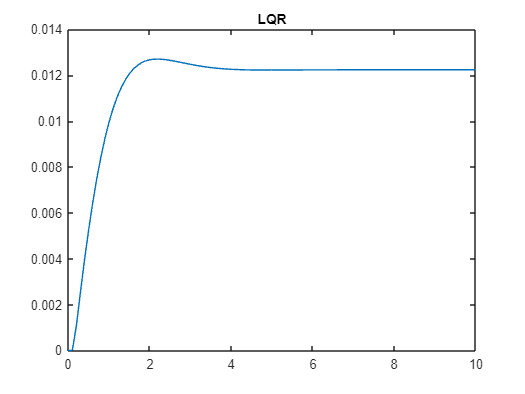

A_LQR=A-B*K12;      %Define new A matrix
g=ss(A_LQR,B,C,D);      %Define new ss
u=1*(t>0);              %Define step
[y,t,~]=lsim(g,u,t);
plot(t,y);
title('LQR');